clc; clear all; close all;

## Odstranění harmonických složek síťového artefaktu z EKG

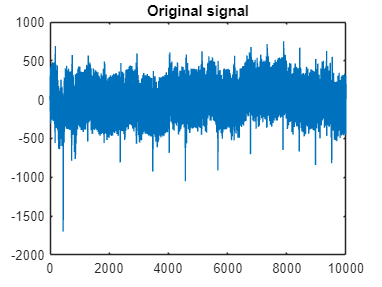

load('EKG3channels_sinus.mat')
x = x(1,:);
x_orig = x;
plot(x)
title('Original signal')

Using the first channel is enough

Fs = 500

### Plot frequency spectrum 

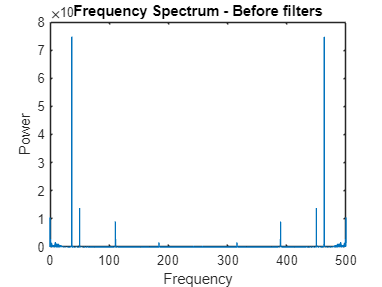

fs = 500;
n = length(x);
f = (0:n-1)*(fs/n);
y = fft(x);
power = abs(y).^2/n;

plot(f, power)
xlabel('Frequency')
ylabel('Power')
title('Frequency Spectrum - Before filters')

- Artefact frequency at freq 0.05 and others

- Remove 2 or 3 frequencies using notch filter (use single notch - comb filter is not ideal for this situation)

- Param Q = 1 is one octave Q = 0.5 means 2 octaves

### Applying notch filters

% fnotch = 0.05
% bandwidth = 2
load("EKG3channels_sinus_filter1.mat")
x = filter(Num, Den, x);

% fnotch = 0.75
% bandwidth = 2
load("EKG3channels_sinus_filter2.mat")
x = filter(Num, Den, x);

% fnotch = 2.75
% Q = 0.5
load("EKG3channels_sinus_filter3.mat")
x = filter(Num, Den, x);

% fnotch = 9.1
% Q = 0.5
load("EKG3channels_sinus_filter4.mat")
x = filter(Num, Den, x);

% fnotch = 14.55
% Q = 0.5
load("EKG3channels_sinus_filter5.mat")
x = filter(Num, Den, x);

### Plot frequency spectrum after filter application

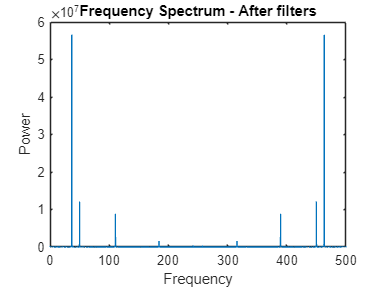

n = length(x);
f = (0:n-1)*(fs/n);
y = fft(x);
power = abs(y).^2/n;

plot(f, power)
xlabel('Frequency')
ylabel('Power')
title('Frequency Spectrum - After filters')

### Plot signal after filter application

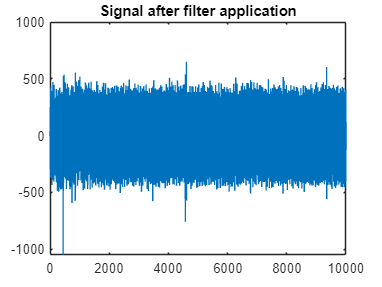

plot(x)
title('Signal after filter application')

### Plot signal before and after filter into single graph

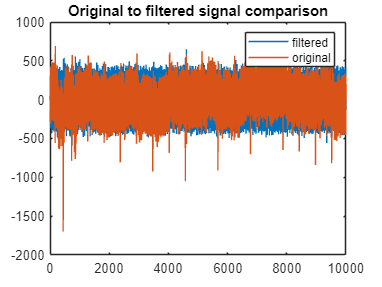

plot(x)
hold on
plot(x_orig)
legend('filtered', 'original')
title('Original to filtered signal comparison')
hold off